clear variables;
%fill in these fields
%filename="03-May-2023 231724.694 2401.099MHz.wav";%beacons on
%filename="03-May-2023 230511.942 2401.099MHz.wav";%beacons off
filename= "04-May-2023 113223.846 2403.000MHz.wav"

filename = "04-May-2023 113223.846 2403.000MHz.wav"

The number of bins used in the fft is: 10000.000000 
 This results in the following resolution: 500.000000


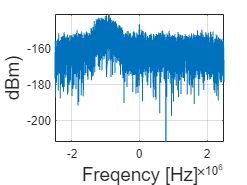

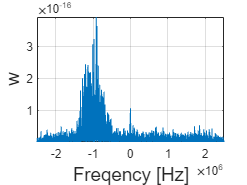

center_freq=2403.000; %in MHz
%bandwith=4;
bandwith=5;
SearchLowFreq= center_freq-(bandwith/2);
SearchHighFreq= center_freq+(bandwith/2);
%Excelname = '';

SDR=audioread(filename,[1,2]);
info = audioinfo(filename);
sampleRate= info.SampleRate;
RecordingTime = info.TotalSamples/sampleRate;

for i = 0:1:floor(RecordingTime-1)
     if i==0
         SDR=audioread(filename,[1,1*sampleRate]);
         IQData = (SDR(:,1)+1i*SDR(:,2)); %Get the IQ data from the columns and put them togheter as a complex value
         IQData= IQData.*blackman(sampleRate);
         [fft_power, fft_dBm] = Precise_FFT_plot(IQData,1,sampleRate,sampleRate,center_freq);
         %[noise_level_dBm(i+1),signal_level_dBm(i+1),snr(i+1), CN0(i+1),peakBin(i+1)] = SNR_V2(fft_power,sampleRate,center_freq,SearchLowFreq,SearchHighFreq,numberOfSatsInView);
     else
         SDR=audioread(filename,[i*sampleRate,(i+1)*sampleRate]);
         IQData = (SDR(:,1)+1i*SDR(:,2)); %Get the IQ data from the columns and put them togheter as a complex value
         IQData= IQData.*blackman(sampleRate+1);
         [fft_power, fft_dBm] = Precise_FFT(IQData,1,sampleRate,sampleRate,center_freq);
         %[noise_level_dBm(i+1),signal_level_dBm(i+1),snr(i+1), CN0(i+1),peakBin(i+1)] = SNR_V2(fft_power,sampleRate,center_freq,SearchLowFreq,SearchHighFreq,numberOfSatsInView);
     end
     
end

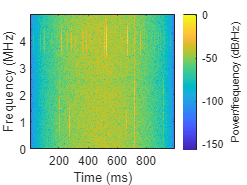

%s= spectrogram(IQData)
%spectrogram(IQData,'yaxis')
%hamming, blackman,boxcar 50%overlap
spectrogram(IQData, hamming(4096), 4096/2, 4096,sampleRate, "yaxis","psd")

time=linspace(1,length(CN0),length(CN0));

Unrecognized function or variable 'CN0'.

plot(time,CN0)
figure
average5samples = ones(1,5)/5;
averaged_CN0 = filter(average5samples,1,CN0);
plot(time,averaged_CN0)
plot(time,peakBin)
%write to excel file
%OutputFile = strcat(Excelname,'.xlsx');
%write_to_excel(:,1) = time';
% write_to_excel(:,2) = CN0';
% write_to_excel(:,3) = averaged_CN0';
% write_to_excel(:,4) = peakBin';
% writematrix(write_to_excel,OutputFile);